# Анализ инженерных данных в MATLAB

Проанализируем сигналы со спутника

## Загрузка данных

Считаем сигналы из Excel-файла

S = readtable('signals.xlsx');
summary(S)

Переведем данные в формат `Timetable`

S = table2timetable(S);

Визуализируем данные таблицы

stackedplot(S);

## Предобработка сигналов

На графике сигнала `Ch3` отчетливо видно несколько выбросов. Заполним их интерполированными значениями

S.Ch3 = filloutliers(S.Ch3, 'linear');
stackedplot(S);

Попробуем посчитать стандартное отклонение сигнала

devs = std(S{:,:})

devs =    NaN   NaN   NaN   NaN


Пропущенные значения (NaN) мешают работать с сигналами

Заменим пропущенные значения

S = fillmissing(S, 'linear');

Теперь можно посчитать статистические характеристики сигналов

means = mean(S{:,:})

means =    -1.7816   -2.8401  -47.5655   25.1878


devs = std(S{:,:})

devs =    52.8533   20.2171  175.7429   26.8842


Проверим, что такт, с которым сняты сигналы, постоянен

isregular(S)

ans = logical
   0


Найдем величину такта

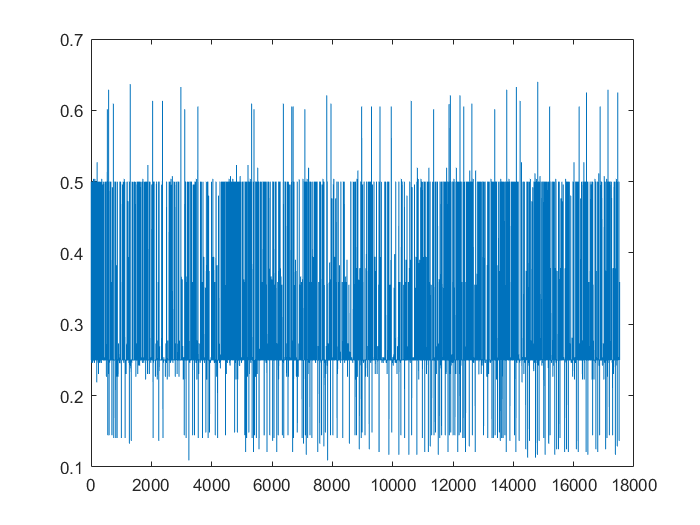

step = seconds(diff(S.Time));
figure
plot(step)

Значение моды такта

mode(step)

ans = 0.2500

Передискретизируем сигналы с тактом 0,25 с

S = retime(S, 'regular', 'linear', 'TimeStep', seconds(0.25));

Передискретизировать можно и с осреднением

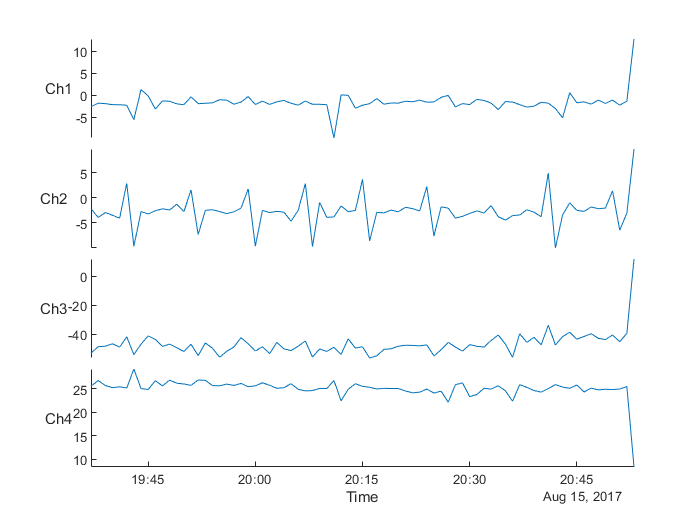

Sm = retime(S, 'minutely', 'mean');
stackedplot(Sm);

Осредним сигналы методом скользящего среднего

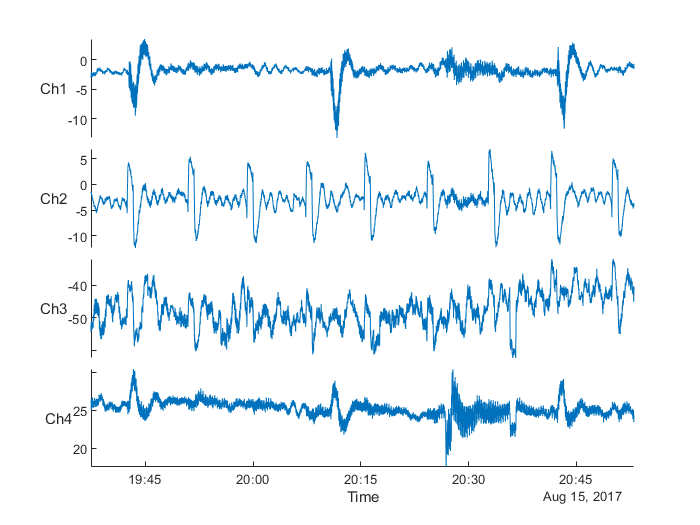

S2 = S;
S2{:,:} = movmean(S2{:,:}, 200);
stackedplot(S2);

## Визуализация сигнала

Построим график второго сигнала

figure
plot(S.Time, S.Ch2);

Наложим сверху осредненный график

hold on
plot(S2.Time, S2.Ch2, 'LineWidth', 1.5);
hold off

Настроим график

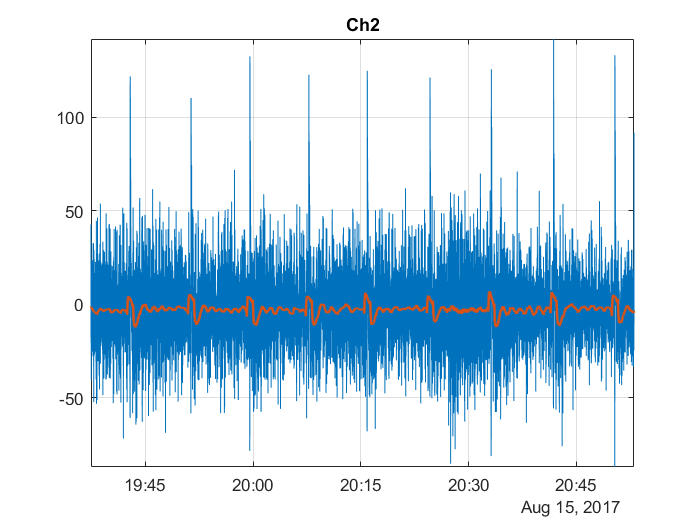

title('Ch2')
grid on
axis tight

## Анализ сигнала

(*Signal Processing Toolbox*)

Переведем вектор времени в формат `duration` (длительность)

S.Time = S.Time - S.Time(1);

Запустим инструмент *Signal Analyzer*

signalAnalyzer(S)

*Pavel Roslovets, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2018*